## Experiment 1

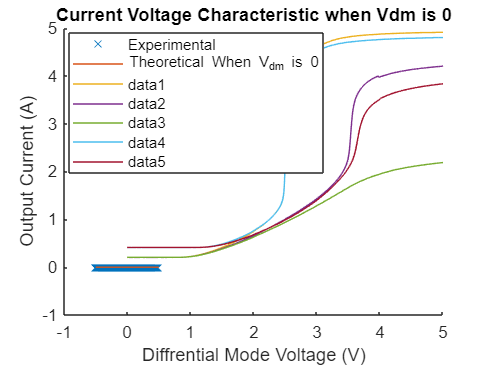

clear;
Ex_1 = load('Ex1_MI_0-7_2-5_Vout.mat');
Ex_2 = load('Ex1_MI_0-7_3-5_Vout.mat');
Ex_3 = load('Ex1_MI_0-7_4-5_Vout.mat');
Ex_4 = load('Ex1_SI_1-5_2-5_Vout.mat');
Ex_5 = load('Ex1_SI_1-5_3-5_Vout.mat');
Ex_6 = load('Ex1_SI_1-5_4-5_Vout.mat');

hold on
plot(Ex_1.V1, Ex_1.Vout)
plot(Ex_2.V1, Ex_2.Vout)
plot(Ex_3.V1, Ex_3.Vout)
plot(Ex_4.V1, Ex_4.Vout)
plot(Ex_5.V1, Ex_5.Vout)

%plot(Ex_6.V1, Ex_6.Vout

## Experiment 2

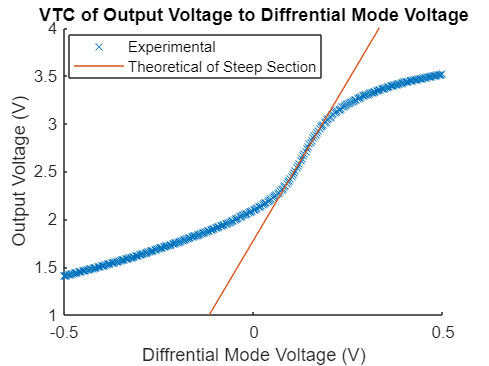

clear; 
clf;
Ex_1 = load('Ex2_1_V2_3-5_Vdm_0.5.mat');
Ex_2 = load('Ex2_2_V2_3-5_Vdm_0.mat');
Ex_3 = load('Ex2_3_V2_3-5_Vdm_0-5.mat');
clf;
hold on
vdm_gain = 6.689;
b = 1.782;
plot(Ex_1.Vdm, Ex_1.Vout, 'x', 'DisplayName', "Experimental")
plot( Ex_1.Vdm, 6.689 .* Ex_1.Vdm + b, 'DisplayName', "Theoretical of Steep Section")
ylim([1 4])
title("VTC of Output Voltage to Diffrential Mode Voltage")
xlabel("Diffrential Mode Voltage (V)")
ylabel("Output Voltage (V)")
legend('location', 'best');
hold off

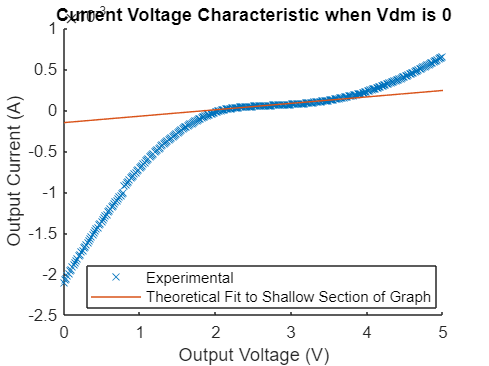

clf;
hold on;
Rout = 7.842e-05;
b =  -0.0001537;
plot(Ex_2.Vout, Ex_2.Iout, 'x', 'DisplayName', "Experimental")
plot(Ex_2.Vout, Rout .* Ex_2.Vout + b, 'DisplayName', "Theoretical Fit to Shallow Section of Graph")
title("Current Voltage Characteristic when Vdm is 0")
xlabel("Output Voltage (V)")
ylabel("Output Current (A)")
legend('location', 'best');
hold off

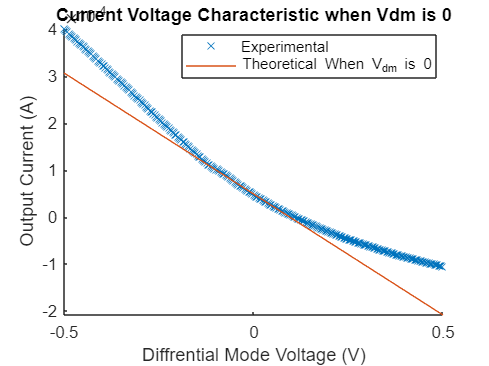

clf;
hold on
incrementalTransconductanceGain =  -0.000516;
b = 4.917e-05;
plot(Ex_3.Vdm, Ex_3.Iout, 'x', 'DisplayName', "Experimental")
plot(Ex_3.Vdm, incrementalTransconductanceGain .* Ex_3.Vdm +b, 'DisplayName', "Theoretical When V_{dm} is 0")
title("Current Voltage Characteristic when Vdm is 0")
xlabel("Diffrential Mode Voltage (V)")
ylabel("Output Current (A)")
legend('location', 'best');
hold off


calcedVdmgain = 1/Rout * incrementalTransconductanceGain

calcedVdmgain = -6.5800

The calculated diffrential mode voltage gain for this experiment is -6.58 and the measured is -6.689. These values are very close to each other.

## Experiment 3

% Code here